# RungeKutta_OscillatoryMotion.m

algorithm designed to plot position and velocity for a harmonic oscillator problem using the 4th Order Runge-Kutta method.

## Define Parameters

iterations = 1000;      % number of iterations in LPA 
m = 0.1;                % mass of object in motion [kg]
x0 = 0.1;               % initial position is at equilibirum
v0 = 0;                 % mass begins motion at rest
dt = 0.001;             % step time inbetween point approximations
k = 10;                 % Spring constant [N/m]
T = (2*pi)*(m/k).^0.5;  % theoretical period
t = 0:((5*T)/1000):5*T; % time elapsed
x = ones(1,iterations); % intiialize position vector to store values
v = ones(1,iterations); % initialize velocity vector to store values

## Calculations

note: to build stages for the next time step, I used a, b, c, d for x and p, q, r, s for v.

x(1) = x0*x(1);             % set initial position
v(1) = v0*v(1);             % set initial velocity

for i = (1:1:iterations)
    a = v(i);
    p = (-k/m).*x(i);
    b = v(i)+(p*dt)/2;
    q = (-k/m).*(x(i)+(a*dt)/2);
    c = v(i)+(q*dt)/2;
    r = (-k/m).*(x(i)+(b*dt)/2);
    d = v(i)+(r*dt);
    s = (-k/m).*(x(i)+(c*dt));
    x(i+1) = x(i) + (1/6)*(a+2*b+2*c+d)*dt;
    v(i+1) = v(i) + (1/6)*(p+2*q+2*r+s)*dt;
end

## Plotting

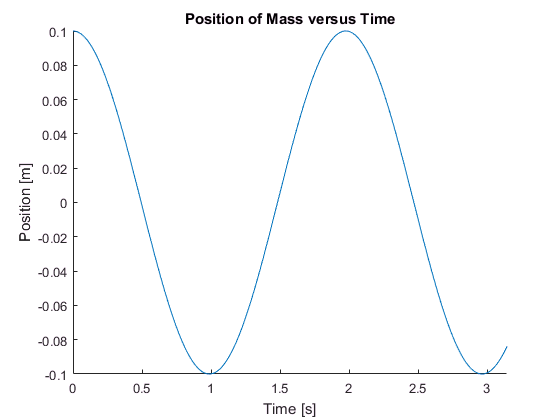

figure(1);                             % create first figure
hold on;

title('Position of Mass versus Time'); % Label title
ylabel('Position [m]');                % Label y axis
xlabel('Time [s]');                    % Label x axis
xlim([0 (5*T)]);                       % set x limits

plot(t,x);                             %plot position vs time

hold off;

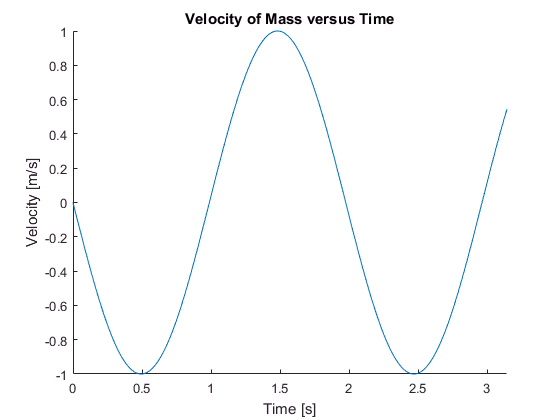


figure(2);                             % create second figure
hold on;

title('Velocity of Mass versus Time'); % Label title
ylabel('Velocity [m/s]');              % Label y axis
xlabel('Time [s]');                    % Label x axis
xlim([0 (5*T)]);                       % set x limits
plot(t,v);                             %plot velocity vs time

hold off;